# Dataset Power Estimates

## Load DataSet

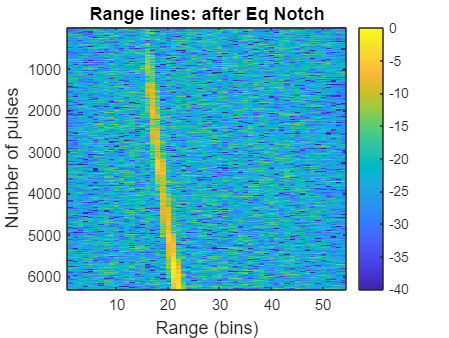


clear all;
close all;


%% Load Data
[FileName,Path2RadarData,filter_index]=uigetfile('','Select Radar Dataset');
RadarData = load([Path2RadarData filesep FileName]);

%% Extract Range Profiles before, after Equalisation and after Notch filtering

RangeProfiles_BeforeEq = RadarData.RangeLines_BeforeEq;
RangeProfiles_AfterEq = RadarData.RangeLines_AfterEq;
RangeProfiles_AfterEqNotch = RadarData.RangeLines_AfterEQ_Notch;

%% Extract other radar parameters

 PRF_Hz = RadarData.Info.PRF_Hz;
 Bandwidth_Hz = RadarData.Info.Bandwidth_Hz;
 RangeStart_m = RadarData.Info.RangeStart_m;
 BlindRange_m = RadarData.Info.BlindRange_m;
 
[NumOfPulses,NumOfRangeBins]=size(RangeProfiles_AfterEqNotch);
fontsize1 = 12;
[MaxRangeLine MaxIdx] = max(max(abs(RangeProfiles_AfterEqNotch)));
clims = [-40 0];
figure; axes('fontsize',fontsize1);
imagesc(20*log10(abs(RangeProfiles_AfterEqNotch)./MaxRangeLine),clims);
colorbar;
xlabel('Range (bins)','fontsize',fontsize1);
ylabel('Number of pulses','fontsize',fontsize1);
title('Range lines: after Eq Notch','fontsize',fontsize1);
hold off 

## Load Ground Truth

dataset = FileName(1:2)

dataset = '01'

dataset = str2num(dataset)

dataset = 1


Target_locations = zeros(NumOfPulses, NumOfRangeBins);

if dataset == 1
    load("Target_locations_DS1.mat");
    Target_locations = Target_locations_DS1;
elseif dataset == 2
    load("Target_locations_DS2.mat");
    Target_locations = Target_locations_DS2;
elseif dataset == 3
    load("Target_locations_DS3.mat");
    Target_locations = Target_locations_DS3;
elseif dataset == 4
    load("Target_locations_DS4.mat");
    Target_locations = Target_locations_DS4;
elseif dataset == 5
    load("Target_locations_DS5.mat");
    Target_locations = Target_locations_DS5;
else 
    load("Target_locations_DS6.mat");
    Target_locations = Target_locations_DS6;
end


## Creation of Signal and Noise Dataset

Signal = [];
Noise = [];

RangeProfiles_AfterEqNotch = abs(RangeProfiles_AfterEqNotch).^2 ;

%splits taget locations and noise into two separate datasets based on
%ground truths
for i = 1:NumOfPulses
    for j = 1:NumOfRangeBins
        if Target_locations(i,j) == 1
            Signal(end +1) = RangeProfiles_AfterEqNotch(i,j);
        else
            Noise(end +1) =  RangeProfiles_AfterEqNotch(i,j);
        end
    end
end


## Mean and Variance Claculations


sig_length = length(Signal);
noise_length = length(Noise);

sig_mean = sum(Signal)/sig_length;
noise_mean = sum(Noise)/noise_length;

Sig_power = (abs(sig_mean))^2

Sig_power = 1.2027e-06

Noise_power = (abs(noise_mean))^2

Noise_power = 2.4215e-09


SNR_dB= 10 * log10(Sig_power / Noise_power)

SNR_dB = 26.9608

## Plot of SNR vs Pd graph

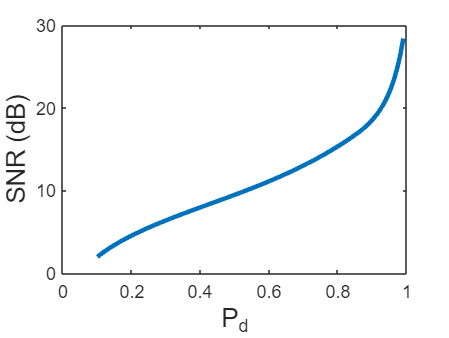

%parameters
pfa = 10^-3;
Pd = 0.1:0.9:0.01;
Pd = linspace(0.1, 0.99, 100);

%dataset extimated as a Swerling Two Model
SNR_Sw2 = zeros(1,length(Pd));

%plotting of graph using shnidman function
for j=1:length(Pd)
    SNR_Sw2(j) = shnidman(Pd(j),pfa,1,2);
end

%plotting
plot(Pd,SNR_Sw2, 'LineWidth', 3)

set(gca, 'FontSize', 12);
xlabel('P_{d}', 'FontSize', 17);
ylabel('SNR (dB)', 'FontSize', 17);


title("Required Single-Pulse SNR for PFA = "+pfa)
